# **INTRODUCCIÓN A LA CUANTIFICACIÓN ESCALAR Y VECTORIAL**

addpath('./datos')
addpath('./funciones')

## **TAREA 1: CUANTIFICACIÓN UNIFORME**

Para x=-2:0.001:2 , xsc=1 y n=3 Representad la salida y el error de cuantificación de los dos cuantificadores respecto a la entrada x. Indicad la zona de error granular y la zona de error de sobrecarga. Ajustad adecuadamente los límites de las gráficas (funciones axis, xlim, ylim,. . . ).

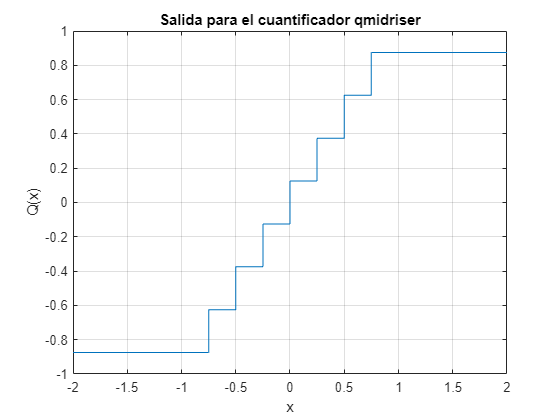

x = -2:0.001:2;
xsc = 1;
n = 3;

[y_QMR, e_QMR] = qmidriser(x, xsc, n);
[y_QMT, e_QMT] = qmidtread(x, xsc, n);

plot (x, y_QMR)
grid on
xlabel('x')
ylabel('Q(x)')
title('Salida para el cuantificador qmidriser')

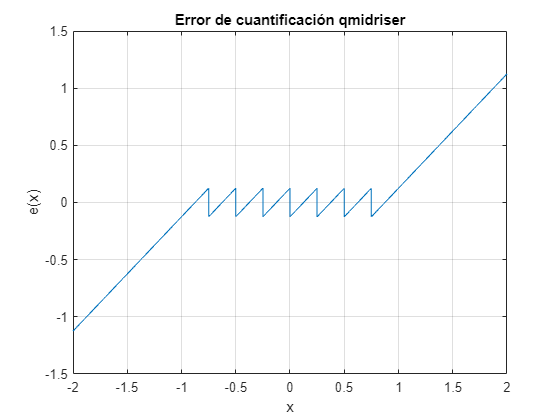


plot (x, e_QMR)
grid on
xlabel('x')
ylabel('e(x)')
title('Error de cuantificación qmidriser')

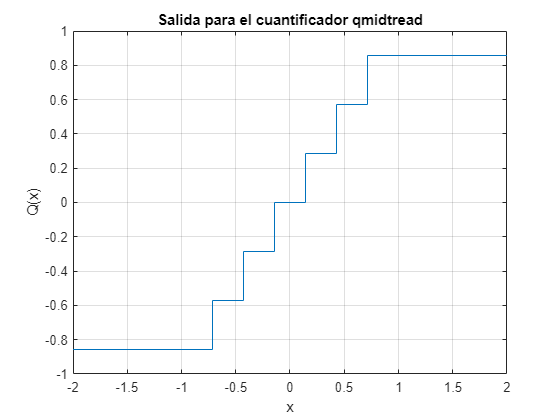


plot (x, y_QMT)
grid on
xlabel('x')
ylabel('Q(x)')
title('Salida para el cuantificador qmidtread')

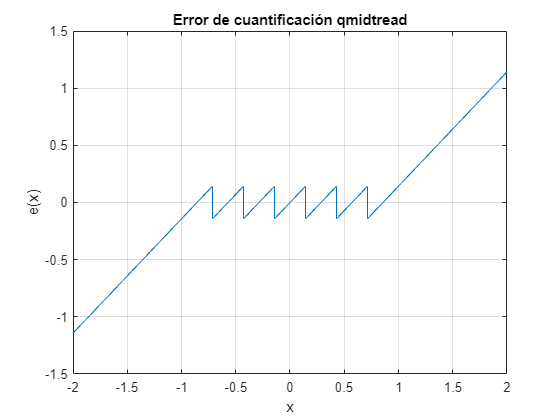


plot (x, e_QMT)
grid on
xlabel('x')
ylabel('e(x)')
title('Error de cuantificación qmidtread')

Para los archivos Afonso_8kHz.wav y Gala_8kHz.wav, muestreados a 8 kHz y 16 bits (128 kbps), cuantificación a 8, 4 y 2 bits, con qmidriser() y qmidtread(), xsc=1. 

- Escuchad y comentad los resultados. (Afonso y Gala) 

- Representad el error de cuantificación. (Gala) 

[Afonso_8kHz, fs] = audioread('Afonso_8khz.wav');
sound(Afonso_8kHz);
xsc = 1;

[Gala_8kHz, fs] = audioread('Gala_8khz.wav');
sound(Gala_8kHz);

### **CUANTIFICACIÓN A 8 BITS**

`AFONSO`

n = 8;
% > Con qmidriser()
[Afonso_QMR_8b, e_Afonso_QMR_8b] = qmidriser(Afonso_8kHz, xsc, n);
sound(Afonso_QMR_8b);

% > Con qmidtread()
[Afonso_QMT_8b, e_Afonso_QMT_8b] = qmidtread(Afonso_8kHz, xsc, n);
sound(Afonso_QMT_8b);

`GALA`

n = 8;
% > Con qmidriser()
[Gala_QMR_8b, e_Gala_QMR_8b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_8b);

% > Con qmidtread()
[Gala_QMT_8b, e_Gala_QMT_8b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_8b);

### **CUANTIFICACIÓN A 4 BITS**

`AFONSO`

n = 4;
% > Con qmidriser()
[Afonso_QMR_4b, e_Afonso_QMR_4b] = qmidriser(Afonso_8kHz, xsc, n);
sound(Afonso_QMR_4b);

% > Con qmidtread()
[Afonso_QMT_4b, e_Afonso_QMT_4b] = qmidtread(Afonso_8kHz, xsc, n);
sound(Afonso_QMT_4b);

`GALA`

n = 4;
% > Con qmidriser()
[Gala_QMR_8b, e_Gala_QMR_4b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_8b);

% > Con qmidtread()
[Gala_QMT_4b, e_Gala_QMT_4b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_4b);

### **CUANTIFICACIÓN A 2 BITS**

`AFONSO`

n = 2;
% > Con qmidriser()
[Afonso_QMR_2b, e_Afonso_QMR_2b] = qmidriser(Afonso_8kHz, xsc, n);
sound(Afonso_QMR_2b);

% > Con qmidtread()
[Afonso_QMT_2b, e_Afonso_QMT_2b] = qmidtread(Afonso_8kHz, xsc, n);
sound(Afonso_QMT_2b);

`GALA`

n = 2;
% > Con qmidriser()
[Gala_QMR_2b, e_Gala_QMR_2b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_2b);

% > Con qmidtread()
[Gala_QMT_2b, e_Gala_QMT_2b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_2b);

Representación de los errores para Gala:

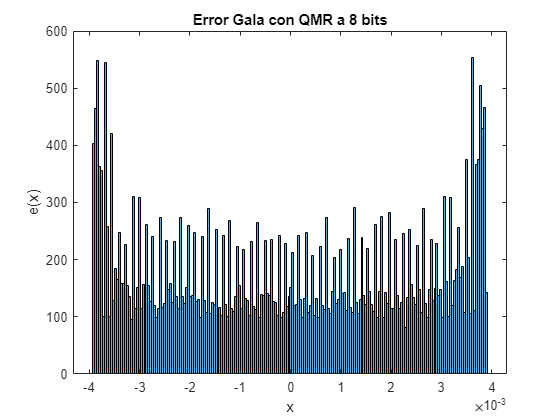

x = Gala_8kHz;

% > Con midriser
% plot (x, e_Gala_QMR_8b)
histogram (e_Gala_QMR_8b, 200)
xlabel('x')
ylabel('e(x)')
title('Error Gala con QMR a 8 bits')

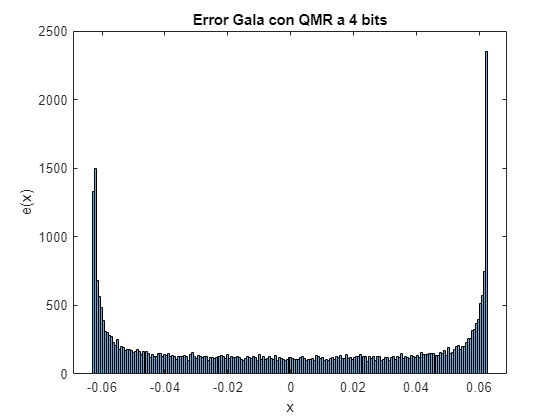


% plot (x, e_Gala_QMR_4b)
histogram (e_Gala_QMR_4b, 200)
xlabel('x')
ylabel('e(x)')
title('Error Gala con QMR a 4 bits')

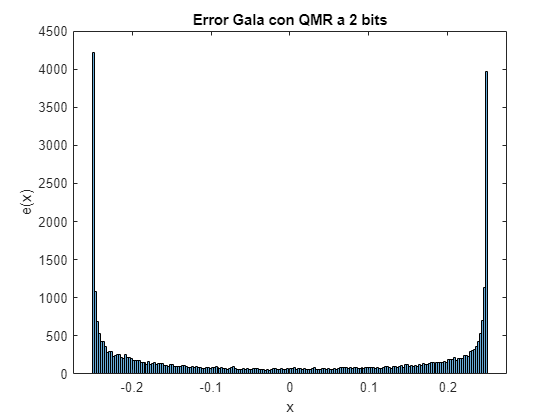


% plot (x, e_Gala_QMR_2b)
histogram (e_Gala_QMR_2b, 200)
xlabel('x')
ylabel('e(x)')
title('Error Gala con QMR a 2 bits')

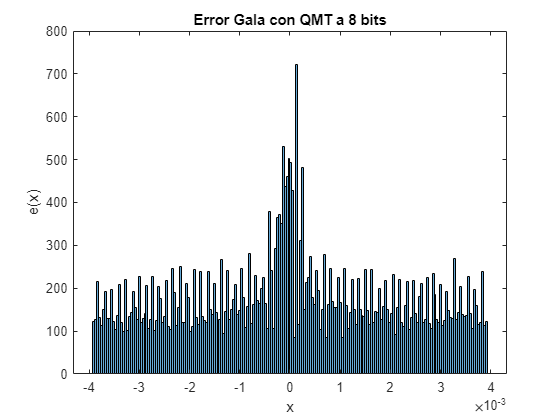


% > Con midtread
% plot (x, e_Gala_QMT_8b)
histogram (e_Gala_QMT_8b, 200)
xlabel('x')
ylabel('e(x)')
title('Error Gala con QMT a 8 bits')

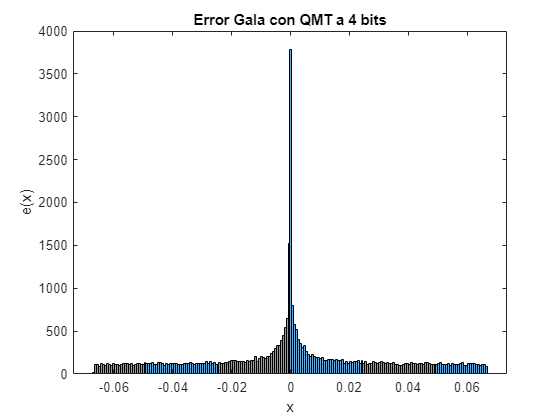


% plot (x, e_Gala_QMT_4b)
histogram (e_Gala_QMT_4b, 200)
xlabel('x')
ylabel('e(x)')
title('Error Gala con QMT a 4 bits')

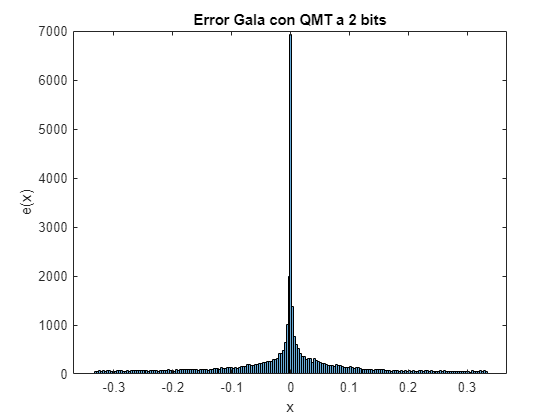


% plot (x, e_Gala_QMT_2b)
histogram (e_Gala_QMT_2b, 200)
xlabel('x')
ylabel('e(x)')
title('Error Gala con QMT a 2 bits')

Repetir para 8 bits, xsc=0.55 y xsc=0.3, con ambos codificadores.

n = 8;

#### **Para 8 bits y xsc = 0.55**

xsc = 0.55;

% > Con qmidriser()
[Gala_QMR_8b, e_Gala_QMR_8b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_8b);

% > Con qmidtread()
[Gala_QMT_8b, e_Gala_QMT_8b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_8b);

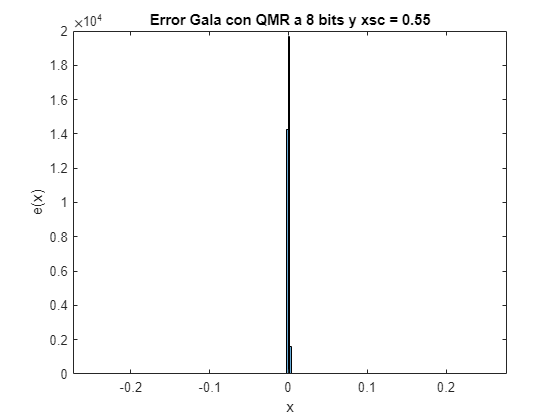

% >> Representación del error usando midriser
% plot (x, e_Gala_QMR_8b)
histogram (e_Gala_QMR_8b, 200)
xlabel('x')
ylabel('e(x)')
title('Error Gala con QMR a 8 bits y xsc = 0.55')

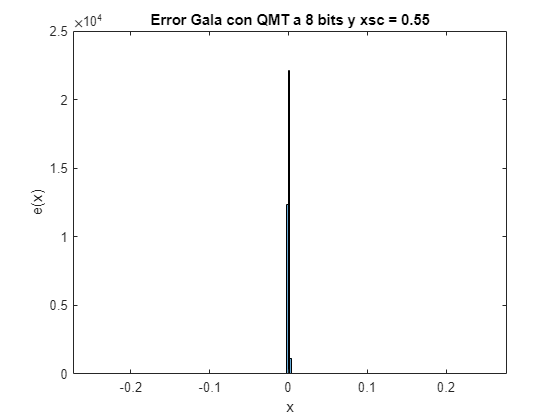


% >> Representación del error usando midtread
% plot (x, e_Gala_QMT_8b)
histogram (e_Gala_QMT_8b, 200)
xlabel('x')
ylabel('e(x)')
title('Error Gala con QMT a 8 bits y xsc = 0.55')

**Para 8 bits y xsc = 0.3**

xsc = 0.3;

% > Con qmidriser()
[Gala_QMR_8b, e_Gala_QMR_8b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_8b);

% > Con qmidtread()
[Gala_QMT_8b, e_Gala_QMT_8b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_8b);

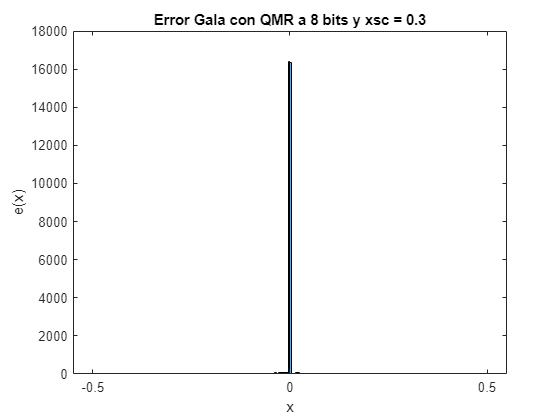

% >> Representación del error usando midriser
% plot (x, e_Gala_QMR_8b)
histogram (e_Gala_QMR_8b, 200)
xlabel('x')
ylabel('e(x)')
title('Error Gala con QMR a 8 bits y xsc = 0.3')

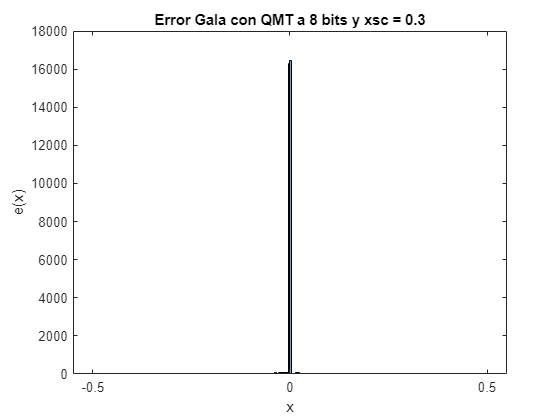


% >> Representación del error usando midtread
% plot (x, e_Gala_QMT_8b)
histogram (e_Gala_QMT_8b, 200)
xlabel('x')
ylabel('e(x)')
title('Error Gala con QMT a 8 bits y xsc = 0.3')